# Low pass filtering of an image using averaging technique

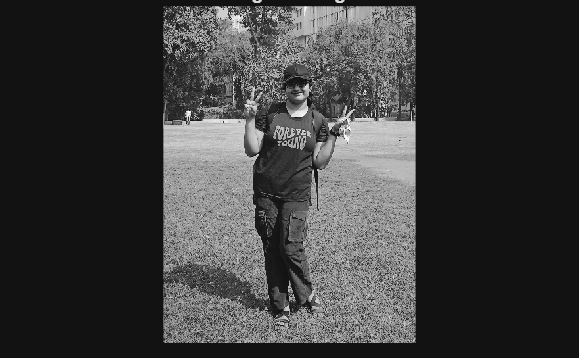

clear all
clc
a = rgb2gray(imread('DK.jpg'));
a = double(a);

[row col] = size(a);

m = input('Enter the mask size ');
n = m^2;

for i = 1:1:m
    for j = 1:1:m
        w(i,j) = 1/n;
    end
end

s = (m+1)/2;

for x = 1:1:row
    for y = 1:1:col
        b(x,y) = a(x,y);
    end
end

for x = s:1:row-s
    for y = s:1:col-s
        b(x,y) = 0;
    end
end

for x = s:1:row-s
    for y = s:1:col-s
        for i = 1:1:m
            for j = 1:1:m
                b(x,y) = a(x-s+i, y-s+j) * w(i,j) + b(x,y);
            end
        end
    end
end

figure(1)
imshow(uint8(a))
title('Original Image')
exportgraphics(gcf, 'LP1.png', 'Resolution', 300)

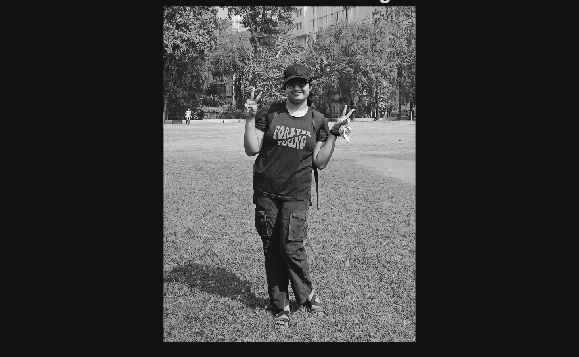


figure(2)
imshow(uint8(b))
title('Low Pass Filtered Image')
exportgraphics(gcf, 'LP2.png', 'Resolution', 300)